% Define the function, assuming a value for t
t = 1; % This is an example; replace it with your actual t value.
f = @(x) (3*x + 50) ./ (sin(5*x) + cos(45*t));

% Compute the numerical integral from 0 to 100
numerical_integral = integral(f, 0, 100);

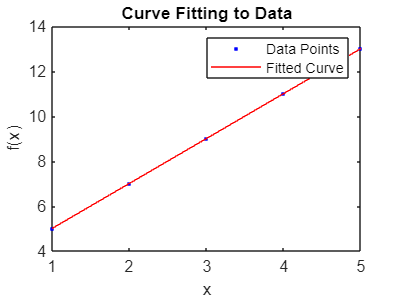

% Given data points
x = [1, 2, 3, 4, 5]; % Example data
y = [5, 7, 9, 11, 13]; % Example data

% Choose the type of fit, e.g., 'linear', 'polynomial', 'rat05' (rational), etc.
fitType = 'poly2'; % for a quadratic polynomial

% Create the fit
[fitresult, gof] = fit(x(:), y(:), fitType);

% Plot the fit
plot(fitresult, x, y);

% Annotate the plot
legend('Data Points', 'Fitted Curve');
xlabel('x');
ylabel('f(x)');
title('Curve Fitting to Data');

syms x
f = sin(x)/x;
T6 = taylor(f,x);
T8 = taylor(f,x,'Order',8);
T10 = taylor(f,x,'Order',10);